addpath("c:/git/UQ4PDE_Homeworks/Homework 3/functions/")
addpath("c:/git/UQ4PDE_Homeworks/Homework 3/Partners work/")

`1) Getting the grid`

I = 8;
x = linspace(0, 1, I+1);
x_half = zeros(I-1, 1);
for i=1:I
    x_half(i) = (x(i+1) + x(i))/2;
end
x_half

x_half =     0.0625
    0.1875
    0.3125
    0.4375
    0.5625
    0.6875
    0.8125
    0.9375


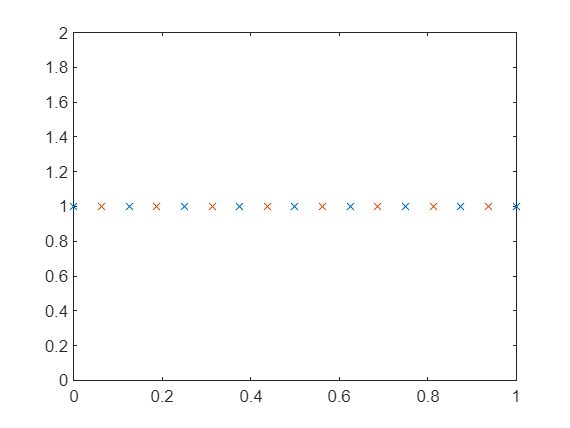


figure()
plot(x, ones(length(x), 1), 'x')
hold on;
plot(x_half, 1*ones(length(x_half), 1), 'x')

`2) Get the corresponding grids for each level`

Lmax = 5;
h0 = 1/2;
h = zeros(Lmax+1, 1);
for l=1:Lmax+1
    h(l) = h0*2^(-l+1);
end
h

h =     0.5000
    0.2500
    0.1250
    0.0625
    0.0312
    0.0156
